SFD and BMD

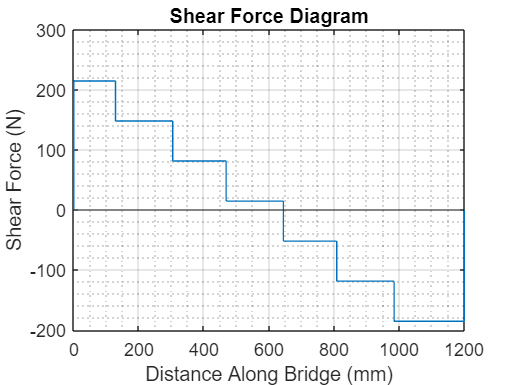

% Design 0

close all;
clear;

x = 76;

y_left = (720-x)/3;
y_right = (x+480)/3;

shear = zeros(1, 16);
shear(1) = 0;
shear(16) = 0;

x_shear = [0, 0, x+52, x+52, x+52+176, x+52+176, x+392, x+392, x+568, x+568, x+732, x+732, x+908, x+908, 1200, 1200];

for i = 1:7
    shear(2*i) = y_left - (200/3)*(i-1);
    shear(2*i+1) = y_left - (200/3)*(i-1);
end
shear;

moment = zeros(1,8);

moment(1) = 0;
moment(8) = 0;

x_moment = [0, x+52, x+52+176, x+392, x+568, x+732, x+908, 1200];


for i = 2:7
    x_val = (x_shear((i-1)*2+1)) - x_shear((i-1)*2-1);
    moment(i) = moment(i-1) + (shear((i-1)*2 + 1) * x_val);
end

moment;

figure
plot(x_shear, shear)
grid on
grid minor
yline(0)
xlabel("Distance Along Bridge (mm)")
ylabel("Shear Force (N)")
title("Shear Force Diagram")

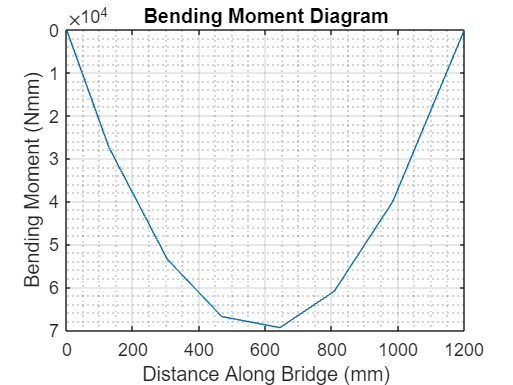


figure
plot(x_moment, moment)
grid on
grid minor
set(gca, 'YDir', 'reverse')  % Flip y-axis
xlabel("Distance Along Bridge (mm)")
ylabel("Bending Moment (Nmm)")
title("Bending Moment Diagram")

SFD and BMD v2

close all;
clear;

% Location of train
x = 0;

L = 1200;  % Length of bridge
n = 1200;  % Discretize into 1 mm seg.
P = 400;  % Total weight of train [N]
lhs_dist = linspace(0, L, n+1);
x_shear_start = (720-x)/3;  % Starting shear at the pin/roller

% One offset because MATLAB indexes with 1
% Another offset to shift cumsum left 1
x_shear_locations = [x+52, x+228, x+392, x+568, x+732, x+908] + 2;
x_train_loads = [-P/6, -P/6, -P/6, -P/6, -P/6, -P/6];

x_shear = zeros(1, L+1);
x_shear(1) = x_shear_start;  % Starting shear at the pin/roller
x_shear(x_shear_locations) = x_train_loads;
x_shear = cumsum(x_shear);  % Final shear force diagram

x_moment = cumsum(x_shear) - x_shear_start;

% Getting x_moment at 0mm -> query x_moment(1+1)
% Getting x_moment at 1mm -> query x_moment(1+1)

Bridge Geometry

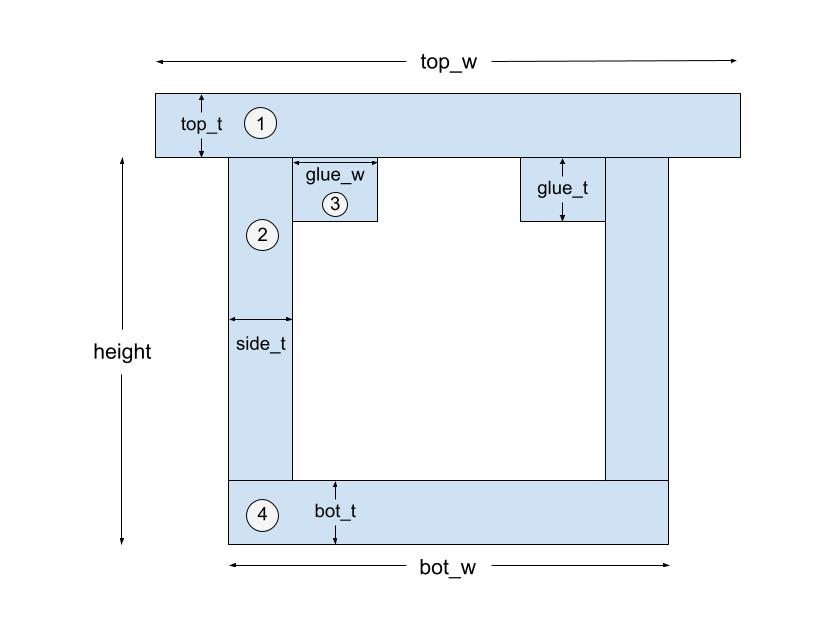

% Define params
top_w = 100;
bot_w = 80;
height = 75; % defined from lowest point without including thickness of the top area
top_t = 1.27;
bot_t = 1.27;
side_t = 1.27;
glue_w = 5; % not including thickness of side
glue_t = 1.27;

Cross-sectional Properties

% Calculate y bar, I, Q_glue, Q_cent
area_1 = top_t * top_w;
area_2 = (height - bot_t)*side_t;
area_3 = glue_w * glue_t;
area_4 = bot_t*bot_w;

y1 = height+top_t/2;
y2 = (height+bot_t)/2;
y3 = height - glue_t/2;
y4 = bot_t/2;

I1 = top_w*(top_t^3)/12;
I2 = side_t*((height-bot_t)^3)/12;
I3 = glue_w*(glue_t^3)/12;
I4 = bot_w*(bot_t^3)/12;

tot_area = area_1 + 2*area_2 + 2*area_3 + area_4;

y_bar = (area_1*y1 + 2*area_2*y2 + 2*area_3*y3 + area_4*y4)/tot_area

y_bar = 41.4311


d1 = y1-y_bar;
d2 = y2-y_bar;
d3 = y3-y_bar;
d4 = y4-y_bar;

sec1 = area_1*(d1^2) + I1;
sec2 = 2*(area_2*(d2^2) + I2);
sec3 = 2*(area_3*(d3^2) + I3);
sec4 = area_4*(d4^2) + I4;

I = sec1+sec2+sec3+sec4

I = 4.1835e+05


Q_cent = (bot_w - 2*side_t)*bot_t*(y_bar - bot_t/2) + 2*y_bar*side_t*y_bar/2

Q_cent = 6.1933e+03

Q_glue = area_1 * (height-y_bar + 1.27/2)

Q_glue = 4.3439e+03

Stresses

% sigma top + bottom, sigma buck tau max tau glue tau buck
[moment_max,x_moment_max] = max(x_moment);
[shear_max,x_shear_max] = max(x_shear)

shear_max = 240

x_shear_max = 1

sigma_top_max = -moment_max *(height+top_t-y_bar)/I;
sigma_bot_max = moment_max *y_bar/I;
shear_max = max(x_shear);
T_cent_max = shear_max * Q_cent/(I*(2*side_t));
T_glue_max = shear_max *Q_glue/(I*(2*glue_w));
sigma_top = -x_moment .* (height+top_t-y_bar)/I

sigma_top =          0   -0.0200   -0.0400   -0.0600   -0.0799   -0.0999   -0.1199   -0.1399   -0.1599   -0.1799   -0.1999   -0.2198   -0.2398   -0.2598   -0.2798   -0.2998   -0.3198   -0.3398   -0.3598   -0.3797   -0.3997   -0.4197   -0.4397   -0.4597   -0.4797   -0.4997   -0.5196   -0.5396   -0.5596   -0.5796   -0.5996   -0.6196   -0.6396   -0.6595   -0.6795   -0.6995   -0.7195   -0.7395   -0.7595   -0.7795   -0.7995   -0.8194   -0.8394   -0.8594   -0.8794   -0.8994   -0.9194   -0.9394   -0.9593   -0.9793


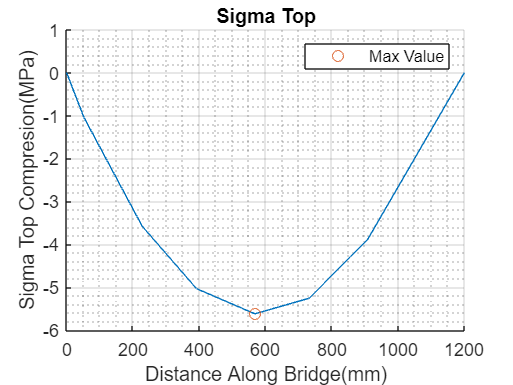

sigma_bot = x_moment .*y_bar/I;
T_cent = x_shear .* Q_cent/(I*(2*side_t));
T_glue = x_shear .* Q_glue/(I*(2*glue_w));


%graph for sigma top
figure
hold on
plot(0:1200,sigma_top)
plot(x_moment_max,sigma_top(x_moment_max),"o")
xlabel("Distance Along Bridge(mm)")
ylabel("Sigma Top Compresion(MPa)")
title("Sigma Top")
grid on
grid minor
legend("","Max Value")

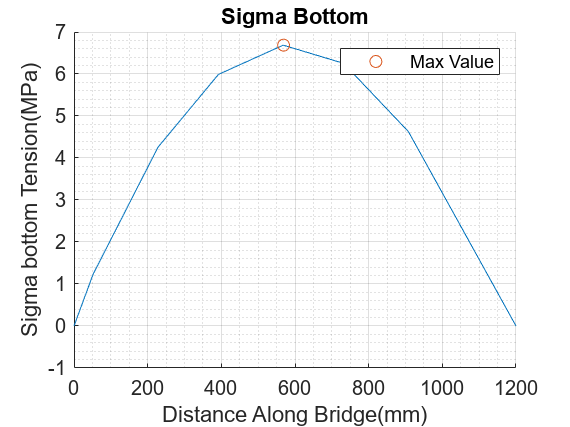

figure

%graph for sigma bottom
hold on
plot(0:1200,sigma_bot)
plot(x_moment_max,sigma_bot(x_moment_max),"o")
xlabel("Distance Along Bridge(mm)")
ylabel("Sigma bottom Tension(MPa)")
grid on
grid minor
legend("","Max Value")
title("Sigma Bottom")

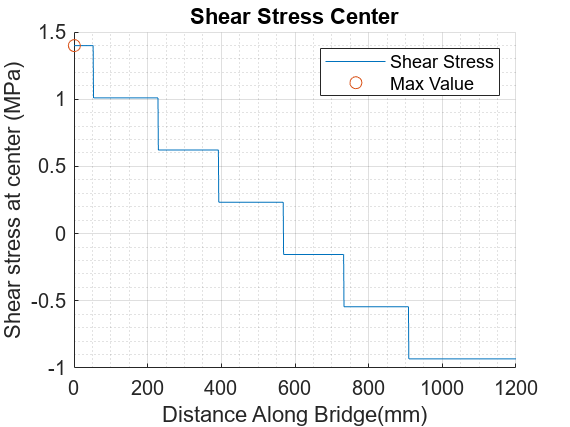

figure
%graph for shear stress at center
hold on
plot(0:1200,T_cent)
plot(x_shear_max,T_cent(x_shear_max),"o")
xlabel("Distance Along Bridge(mm)")
ylabel("Shear stress at center (MPa)")
grid on
grid minor
legend("Shear Stress","Max Value")
title("Shear Stress Center")

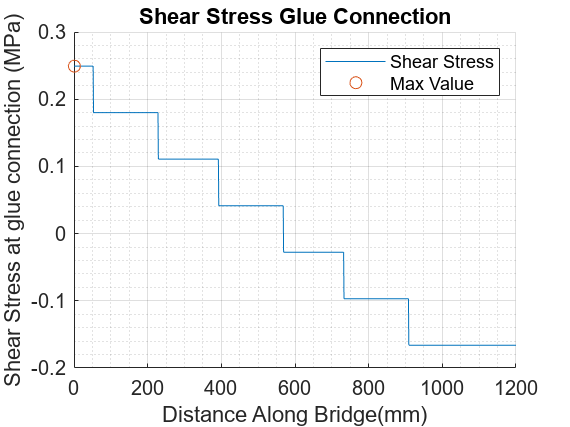

figure

%graph for shear stress at glue connection
hold on
plot(0:1200,T_glue)
plot(x_shear_max,T_glue(x_shear_max),"o")
xlabel("Distance Along Bridge(mm)")
ylabel("Shear Stress at glue connection (MPa)")
grid on
grid minor
legend("Shear Stress","Max Value")
title("Shear Stress Glue Connection")

figure


% Amin

Thin Plate

% Kevin
E = 4000

E = 4000

mu = 0.2

mu = 0.2000


% Case 1.1: buckling of the top plate
t11 = bot_t

t11 = 1.2700

b11 = bot_w - side_t

b11 = 78.7300

stress_top_plate = (4*pi^2*E)/(12*(1-mu^2)) * (t11/b11)^2

stress_top_plate = 3.5669


% Case 1.2: buckling of the bottom plate
t12 = top_t

t12 = 1.2700

b12 = bot_w - side_t

b12 = 78.7300

stress_bottom_plate = (4*pi^2*E)/(12*(1-mu^2)) * (t12/b12)^2

stress_bottom_plate = 3.5669


% Case 2.1: buckling of the side flanges
t_flange = top_t

t_flange = 1.2700

b_out = (top_w-bot_w)/2 + side_t/2

b_out = 10.6350

stress_side_flange = (0.425*pi^2*E)/(12*(1-mu^2)) * (t_flange/b_out)^2

stress_side_flange = 20.7696


% Case 3.1: buckling due to varying shears
t_web31 = side_t

t_web31 = 1.2700

y_top = height - y_bar

y_top = 33.5689

stress_varying_shear = (6*pi^2*E)/(12*(1-mu^2)) * (t_web31/y_top)^2

stress_varying_shear = 29.4301


% Case 4.1: shear buckling
t_web41 = side_t

t_web41 = 1.2700

h_web41 = height - glue_t/2 - bot_t/2

h_web41 = 73.7300

a = 400

a = 400

stress_shear_buckle = (5*pi^2*E)/(12*(1-mu^2)) * ((t_web41/h_web41)^2 + (t_web41/a)^2)

stress_shear_buckle = 5.2566

Factor of Safety

sigma_tens = 30

sigma_tens = 30

sigma_comp = 6

sigma_comp = 6

shear_strength = 4

shear_strength = 4

shear_strength_glue = 2

shear_strength_glue = 2



FOS_tension = sigma_tens./sigma_bot;
FOS_comp = -sigma_comp./sigma_top;
FOS_flexbuck1 = -stress_top_plate ./sigma_top;
FOS_flexbuck2 = -stress_side_flange ./ sigma_top;
FOS_flexbuck3 = -stress_bottom_plate ./ sigma_top;

FOS_shear = shear_strength ./ T_cent

FOS_shear =     2.8596    2.8596    2.8596    2.8596    2.8596    2.8596    2.8596    2.8596    2.8596    2.8596    2.8596    2.8596    2.8596    2.8596    2.8596    2.8596    2.8596    2.8596    2.8596    2.8596    2.8596    2.8596    2.8596    2.8596    2.8596    2.8596    2.8596    2.8596    2.8596    2.8596    2.8596    2.8596    2.8596    2.8596    2.8596    2.8596    2.8596    2.8596    2.8596    2.8596    2.8596    2.8596    2.8596    2.8596    2.8596    2.8596    2.8596    2.8596    2.8596    2.8596


FOS_shear_glue = shear_strength_glue ./T_glue

FOS_shear_glue =     8.0257    8.0257    8.0257    8.0257    8.0257    8.0257    8.0257    8.0257    8.0257    8.0257    8.0257    8.0257    8.0257    8.0257    8.0257    8.0257    8.0257    8.0257    8.0257    8.0257    8.0257    8.0257    8.0257    8.0257    8.0257    8.0257    8.0257    8.0257    8.0257    8.0257    8.0257    8.0257    8.0257    8.0257    8.0257    8.0257    8.0257    8.0257    8.0257    8.0257    8.0257    8.0257    8.0257    8.0257    8.0257    8.0257    8.0257    8.0257    8.0257    8.0257


FOS_shear_buck = stress_shear_buckle ./ T_cent

FOS_shear_buck =     3.7579    3.7579    3.7579    3.7579    3.7579    3.7579    3.7579    3.7579    3.7579    3.7579    3.7579    3.7579    3.7579    3.7579    3.7579    3.7579    3.7579    3.7579    3.7579    3.7579    3.7579    3.7579    3.7579    3.7579    3.7579    3.7579    3.7579    3.7579    3.7579    3.7579    3.7579    3.7579    3.7579    3.7579    3.7579    3.7579    3.7579    3.7579    3.7579    3.7579    3.7579    3.7579    3.7579    3.7579    3.7579    3.7579    3.7579    3.7579    3.7579    3.7579


Shear Force Capacities + Bending Moment Capacities

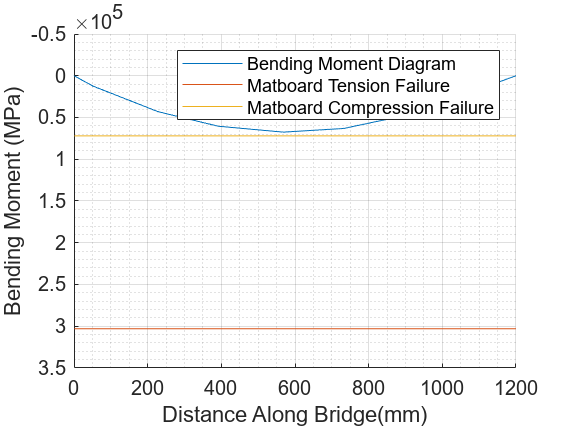

M_fail_tens = FOS_tension .* x_moment;
M_fail_comp = FOS_comp .* x_moment;
M_fail_buck1 = FOS_flexbuck1 .*x_moment;
M_fail_buck2 = FOS_flexbuck2 .* x_moment;
M_fail_buck3 = FOS_flexbuck3 .* x_moment;

M_fail_shear = FOS_shear .* x_shear;
M_fail_shear_glue = FOS_shear_glue .* x_shear;
M_fail_shear_buck = FOS_shear_buck .* x_shear;

figure
hold on;
set(gca, 'YDir', 'reverse') 
plot(0:1200, x_moment)
plot(0:1200, M_fail_tens)
plot(0:1200, M_fail_comp)
xlabel("Distance Along Bridge(mm)")
ylabel("Bending Moment (MPa)")
grid on
grid minor
legend("Bending Moment Diagram", "Matboard Tension Failure", "Matboard Compression Failure")
hold off;

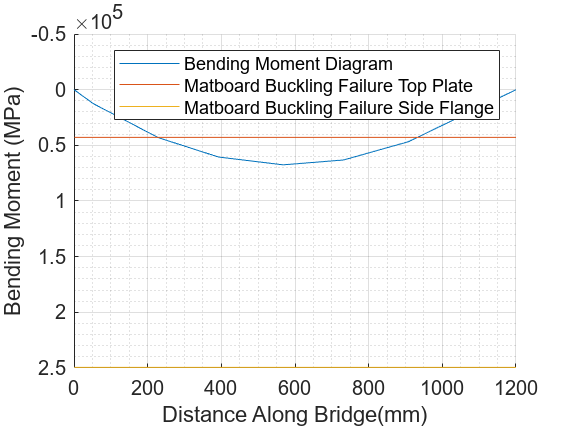


figure
hold on;
set(gca, 'YDir', 'reverse') 
plot(0:1200, x_moment)
plot(0:1200, M_fail_buck1)
plot(0:1200, M_fail_buck2)
xlabel("Distance Along Bridge(mm)")
ylabel("Bending Moment (MPa)")
grid on
grid minor
legend("Bending Moment Diagram", "Matboard Buckling Failure Top Plate", "Matboard Buckling Failure Side Flange")
hold off;

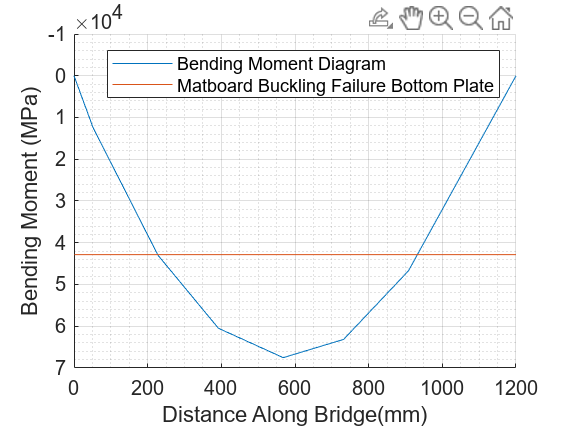


figure
hold on;
set(gca, 'YDir', 'reverse') 
plot(0:1200, x_moment)
plot(0:1200, M_fail_buck3)
xlabel("Distance Along Bridge(mm)")
ylabel("Bending Moment (MPa)")
grid on
grid minor
legend("Bending Moment Diagram", "Matboard Buckling Failure Bottom Plate")
hold off;

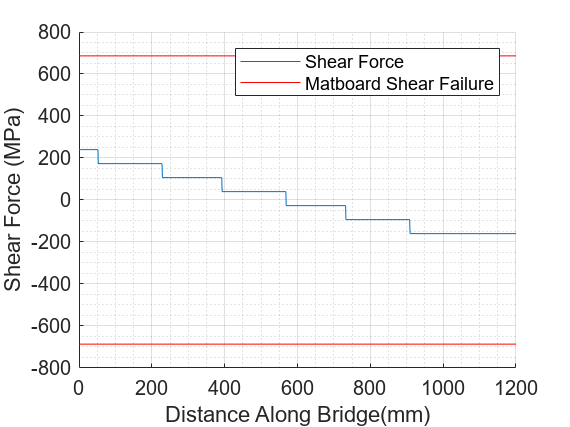


figure
hold on
plot(0:1200, x_shear)
plot(0:1200, M_fail_shear,"r")
plot(0:1200, -M_fail_shear,"r")
xlabel("Distance Along Bridge(mm)")
ylabel("Shear Force (MPa)")
grid on
grid minor
legend("Shear Force","Matboard Shear Failure")
hold off

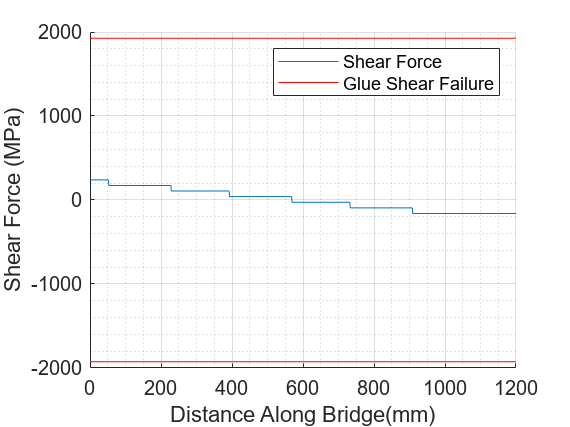




figure 
hold on 
plot(0:1200, x_shear)
plot(0:1200, M_fail_shear_glue,"r")
plot(0:1200, -M_fail_shear_glue,"r")
legend("Shear Force","Glue Shear Failure")
xlabel("Distance Along Bridge(mm)")
ylabel("Shear Force (MPa)")
grid on
grid minor
hold off

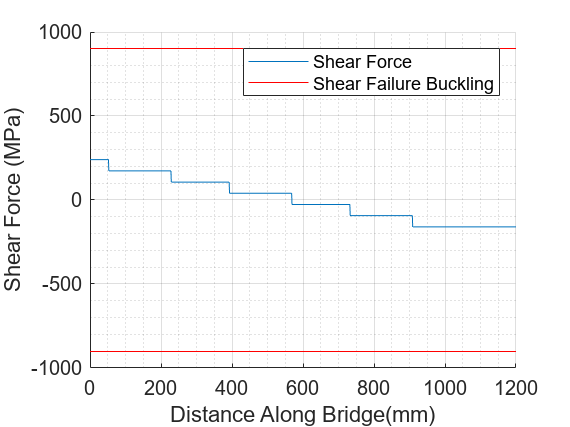


figure 
hold on 
plot(0:1200, x_shear)
plot(0:1200, M_fail_shear_buck,"r")
plot(0:1200, -M_fail_shear_buck,"r")
legend("Shear Force","Shear Failure Buckling")
xlabel("Distance Along Bridge(mm)")
ylabel("Shear Force (MPa)")
grid on
grid minor
hold off